# swing foot trajectory

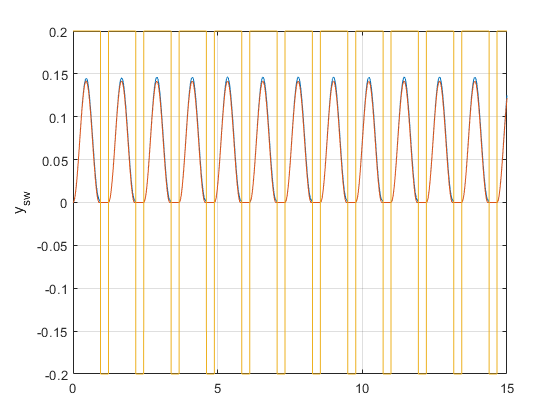

th1 = simout(:,1);
th2 = simout(:,2);
th3 = simout(:,3);
th4 = simout(:,4);
th5 = simout(:,5);

dth1 = simout(:,6);
dth2 = simout(:,7);
dth3 = simout(:,8);
dth4 = simout(:,9);
dth5 = simout(:,10);

x_sw = params.l1*cos(th1) + params.l2*cos(th1 + th2) + params.l3*cos(th1 + th2 + th3) + params.l4*cos(th1 + th2 + th3 + th4);
y_sw = params.l1*sin(th1) + params.l2*sin(th1 + th2) + params.l3*sin(th1 + th2 + th3) + params.l4*sin(th1 + th2 + th3 + th4);

dy_sw = params.l1*cos(th1).*(dth1) + params.l2*cos(th1 + th2).*(dth1 + dth2) + params.l3*cos(th1 + th2 + th3).*(dth1 + dth2 + dth3) + params.l4*cos(th1 + th2 + th3 + th4).*(dth1 + dth2 + dth3 + dth4);

figure()
plot(time, y_sw)
hold on
plot(time, sw_ft_des(:,2))
plot(time, 0.2*flag(:,1))
ylabel('y_{sw}')
grid on

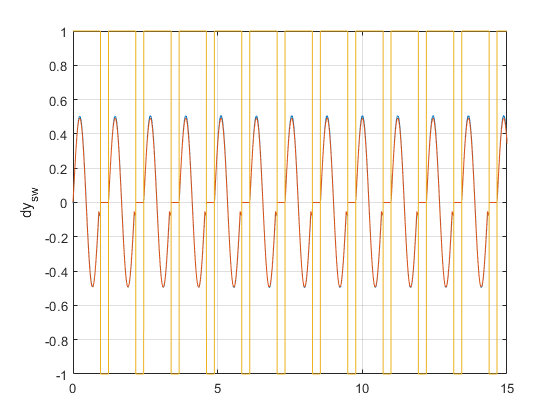


figure()
plot(time, dy_sw)
hold on
plot(time, sw_ft_des(:,4))
plot(time, flag(:,1))
ylabel('dy_{sw}')
grid on

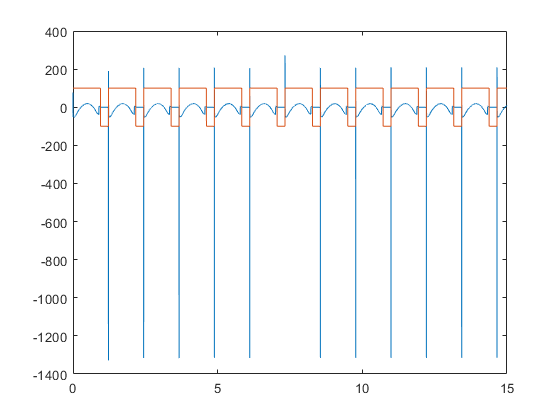


figure()
plot(time, force(:,4))
hold on
plot(time, 100*flag(:,1))